# MATLAB code used in Kobayashi & Matsuo, *Cell Reports* (2023)

Environment Decoding

GitHub: [https://github.com/KyogoSKobayashi/Kobayashi_and_Matsuo_CellReports2023](https://github.com/KyogoSKobayashi/Kobayashi_and_Matsuo_CellReports2023)

Zenodo: [https://doi.org/10.5281/zenodo.7445183](https://doi.org/10.5281/zenodo.7445183)

- License

- Generate Demo Data

- Calcium Event Detetion

# License

## KyogoSKobayashi/Kobayashi_and_Matsuo_CellReports2023 is licensed under the MIT License

A short and simple permissive license with conditions only requiring preservation of copyright and license notices. Licensed works, modifications, and larger works may be distributed under different terms and without source code.

`MIT License`

`Copyright (c) 2022 KyogoSKobayashi`

`Permission is hereby granted, free of charge, to any person obtaining a copy`

`of this software and associated documentation files (the "Software"), to deal`

`in the Software without restriction, including without limitation the rights`

`to use, copy, modify, merge, publish, distribute, sublicense, and/or sell`

`copies of the Software, and to permit persons to whom the Software is`

`furnished to do so, subject to the following conditions:`

`The above copyright notice and this permission notice shall be included in all`

`copies or substantial portions of the Software.`

`THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR`

`IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,`

`FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE`

`AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER`

`LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM,`

`OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE`

`SOFTWARE.`

# Generate DEMO data

- dFF0_data: 1600 frames-by-30 cells matrix of ΔF / F0 data .

- Session_labels: 4-by-1 string vector; "A1","A2","B1", and "B2".

- Frame_idx:  1600-by-1 string vector; "A1","A2","B1", or "B2".

recording_Hz = 20; 

num_of_recording_frames_of_a_session = 400; % 20/400 = 20 sec
num_of_recording_cells = 30;

dFF0_data=zeros(num_of_recording_frames_of_a_session*4,num_of_recording_cells);
Session_labels = ["A1";"A2";"B1";"B2"];
Frame_idx = [repmat(Session_labels(1),num_of_recording_frames_of_a_session,1);...
             repmat(Session_labels(2),num_of_recording_frames_of_a_session,1);...
             repmat(Session_labels(3),num_of_recording_frames_of_a_session,1);...
             repmat(Session_labels(4),num_of_recording_frames_of_a_session,1)];

[~, y0] = titanium; %1-by-49 vector

rng default % for reproducibily
y1 = [y0,0.6]; %1-by-50 vector
y2 = y1-min(y1); %1-by-50 vector, represents a calcium event
one_event_trace = y2+(0.5-rand(size(y2)))/3; %1-by-50 vector with noise
no_event_trace = (0.5-rand(size(y2)))/3; %1-by-50 vector, bakcground fluctuation

% high activity data
high_activity_data = [];
for ff = 1:(num_of_recording_frames_of_a_session/numel(y2))
    r = rand(1);
    if r > 0.3
        y = one_event_trace;
    else
        y = no_event_trace;
    end
    high_activity_data = [high_activity_data, y];
end

% low activity data
low_activity_data = [];
for ff = 1:(num_of_recording_frames_of_a_session/numel(y2))
    r = rand(1);
    if r > 0.8
        y = one_event_trace;
    else
        y = no_event_trace;
    end
    low_activity_data = [low_activity_data, y];
end

f = Frame_idx == "A1";
d = high_activity_data;
for cc = 1:num_of_recording_cells
    r = randperm(num_of_recording_frames_of_a_session,1);
    dFF0_data(f,cc) = [d(r:end),d(1:r-1)];
end

f = Frame_idx == "A2";
d = high_activity_data;
for cc = 1:num_of_recording_cells
    r = randperm(num_of_recording_frames_of_a_session,1);
    dFF0_data(f,cc) = [d(r:end),d(1:r-1)];
end

f = Frame_idx == "B1";
d = low_activity_data;
for cc = 1:num_of_recording_cells
    r = randperm(num_of_recording_frames_of_a_session,1);
    dFF0_data(f,cc) = [d(r:end),d(1:r-1)];
end

f = Frame_idx == "B2";
d = low_activity_data;
for cc = 1:num_of_recording_cells
    r = randperm(num_of_recording_frames_of_a_session,1);
    dFF0_data(f,cc) = [d(r:end),d(1:r-1)];
end

# Prepare a Trainging Data Set and Labels

class_names={'EnvironmentA','EnvironmentB'};
env_label=cell(size(Frame_idx));
env_label(contains(Frame_idx,"A"))=repmat(class_names(1),...
    sum(contains(Frame_idx,"A")),1);
env_label(contains(Frame_idx,"B"))=repmat(class_names(2),...
    sum(contains(Frame_idx,"B")),1);

train_session=["B1","A1"];
train_data=[];
train_label={};
for ss=1:numel(train_session)
    train_data=[train_data;dFF0_data(Frame_idx==(train_session(ss)),:)];
    train_label=[train_label;env_label(Frame_idx==train_session(ss))];
end

# Prepare a Test Data Set and Labels

test_session=["B2","A2"];
test_data=[];
test_label={};
for ss=1:numel(test_session)
    test_data=[test_data;dFF0_data(Frame_idx==(test_session(ss)),:)];
    test_label=[test_label;env_label(Frame_idx==test_session(ss))];
end

# Build a Decoding Model

rng('default') % for reproducibility

zscored_train_data=zscore(train_data)';
[Mdl,FitInfo,HyperparameterOptimizationResults] = fitclinear(zscored_train_data,...
    train_label,'ClassNames',class_names,'ObservationsIn','columns','Solver',...
    'sparsa','OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus','Verbose',0,...
    'ShowPlots',false));

# Predict the Environemnt

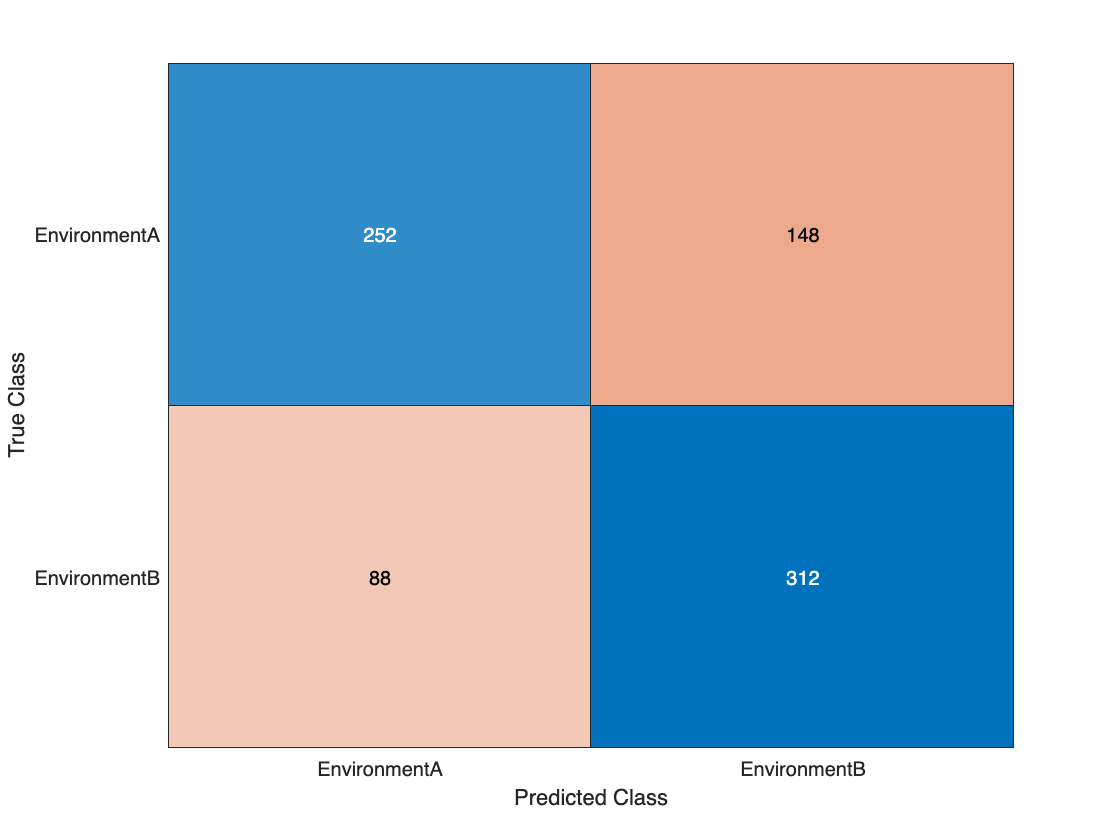

zscored_test_data=zscore(test_data);
predicted_label = predict(Mdl,zscored_test_data);
confusionchart(test_label,predicted_label)